# Kinematic DH Parameters for 3-link RPR arm

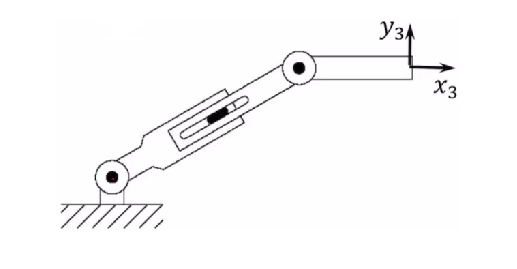

imshow(imread("./figures/RPR.png"))

### Robot Description

- **{r, p, r} : **r for revolute, p for prismatic

- **{0, 0, L_1} : **radius lenghts

- **{Pi/2, -Pi/2, 0} :** link twists

- **{0, q_2, 0} : **link offset rotation

- **{q1, 0, q3} : **joint rotation

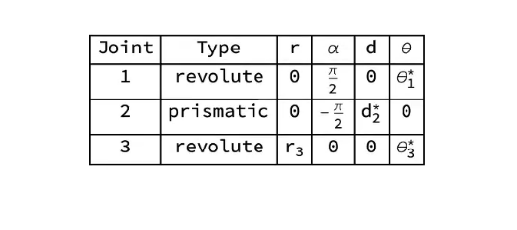

imshow(imread("./figures/DH.png"))

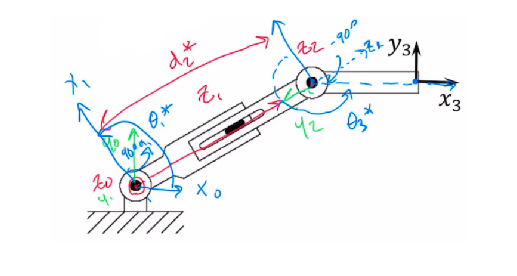

imshow(imread("./figures/annotated_RPR.png"))


$$A_i ={\textrm{Rot}}_{z,\theta_i } {\textrm{Trans}}_{z,d_i } {\textrm{Trans}}_{x,\alpha_i } {\textrm{Rot}}_{x,\alpha_i }$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i }  & 0 & 0\\
s_{\theta_i }  & c_{\theta_i }  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & \alpha_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 1 & 0\\
0 & c_{\alpha_i }  & -s_{\alpha_i }  & 0\\
0 & s_{\alpha_i }  & c_{\alpha_i }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i } c_{\alpha_i }  & s_{\theta_i } c_{\alpha_i }  & a_i c_{\theta_i } \\
s_{\theta_i }  & c_{\theta_i } c_{\alpha_i }  & -c_{\theta_i } s_{\alpha_i }  & a_i s_{\theta_i } \\
0 & s_{\alpha_i }  & c_{\alpha_i }  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The DH parameters define the geometry of how each rigid body attaches to its parent via a joint. The parameters follow a four transformation convention:

- $A$ — Length of the common normal line between the two *z*-axes, which is perpendicular to both axes

- $\alpha$ — Angle of rotation for the common normal

- $d$ — Offset along the *z*-axis in the normal direction, from parent to child

- $\theta$ — Angle of rotation for the *x*-axis along the previous *z*-axis

Specify the parameters for the system as a matrix. Values come from 

clc
clear
close all


syms t1 d2 t3 Xe Ye Te;

dhparams = [0   	 pi/2	    0   	t1 ;
            0	    -pi/2       d2      0  ;
            10	     0	        0	    t3 ];


H0_1 = DH(dhparams(1,1), dhparams(1,2), dhparams(1,3), dhparams(1,4))
H1_2 = DH(dhparams(2,1), dhparams(2,2), dhparams(2,3), dhparams(2,4))
H2_3 = DH(dhparams(3,1), dhparams(3,2), dhparams(3,3), dhparams(3,4))

$$H0\_1 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & 0 & \sin\left(t_{1}\right) & 0\\ \sin\left(t_{1}\right) & 0 & -\cos\left(t_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$H1\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0_2 = H0_1*H1_2

$$H2\_3 = \left(\begin{array}{cccc} \cos\left(t_{3}\right) & -\sin\left(t_{3}\right) & 0 & 10\,\cos\left(t_{3}\right)\\ \sin\left(t_{3}\right) & \cos\left(t_{3}\right) & 0 & 10\,\sin\left(t_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0_3 = H0_1*H1_2*H2_3

O1_x = simplify(H0_1(1,4))

$$H0\_2 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & d_{2}\,\sin\left(t_{1}\right)\\ \sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O1_y = simplify(H0_1(2,4))

$$H0\_3 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 10\,\cos\left(t_{1}\right)\,\cos\left(t_{3}\right)-10\,\sin\left(t_{1}\right)\,\sin\left(t_{3}\right)+d_{2}\,\sin\left(t_{1}\right)\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 10\,\cos\left(t_{1}\right)\,\sin\left(t_{3}\right)+10\,\cos\left(t_{3}\right)\,\sin\left(t_{1}\right)-d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(t_{1}\right)\,\cos\left(t_{3}\right)-\sin\left(t_{1}\right)\,\sin\left(t_{3}\right)\\ \sigma_{2}=\cos\left(t_{3}\right)\,\sin\left(t_{1}\right)\\ \sigma_{3}=\cos\left(t_{1}\right)\,\sin\left(t_{3}\right) \end{array}$$


O2_x = simplify(H0_2(1,4))

$$O1\_x = 0$$

O2_y = simplify(H0_2(2,4))

$$O1\_y = 0$$


O3_x = simplify(H0_3(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O3_y = simplify(H0_3(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


xeq = Xe == O3_x

$$O3\_x = 10\,\cos\left(t_{1}+t_{3}\right)+d_{2}\,\sin\left(t_{1}\right)$$

yeq = Ye == O3_y

$$O3\_y = 10\,\sin\left(t_{1}+t_{3}\right)-d_{2}\,\cos\left(t_{1}\right)$$

teq = Te == pi-t1-t3


$$xeq = \mathrm{Xe}=10\,\cos\left(t_{1}+t_{3}\right)+d_{2}\,\sin\left(t_{1}\right)$$

S = solve([xeq yeq teq],[t1 d2 t3])

$$yeq = \mathrm{Ye}=10\,\sin\left(t_{1}+t_{3}\right)-d_{2}\,\cos\left(t_{1}\right)$$

$$teq = \mathrm{Te}=3.1416-t_{3}-t_{1}$$

simplify(S.t1)
simplify(S.d2)

S = struct with fields:
    t1: [2×1 sym]
    d2: [2×1 sym]
    t3: [2×1 sym]


simplify(S.t3)


$$ans = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-10\,\sin\left(\mathrm{Te}\right)+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)+3.1416\\ 3.1416-2\,\mathrm{atan}\left(\frac{10\,\sin\left(\mathrm{Te}\right)-\mathrm{Ye}+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}} \end{array}$$

t_1 = simplify(S.t1)

$$ans = \left(\begin{array}{c} -0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}}\\ 0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}} \end{array}\right)$$

d_2 = simplify(S.d2)

$$ans = \begin{array}{l} \left(\begin{array}{c} -\mathrm{Te}-2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-10\,\sin\left(\mathrm{Te}\right)+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)\\ 2\,\mathrm{atan}\left(\frac{10\,\sin\left(\mathrm{Te}\right)-\mathrm{Ye}+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)-\mathrm{Te} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}} \end{array}$$

t_3 = simplify(S.t3)


$$t\_1 = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-10\,\sin\left(\mathrm{Te}\right)+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)+3.1416\\ 3.1416-2\,\mathrm{atan}\left(\frac{10\,\sin\left(\mathrm{Te}\right)-\mathrm{Ye}+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}} \end{array}$$

t_3(2)

$$d\_2 = \left(\begin{array}{c} -0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}}\\ 0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}} \end{array}\right)$$

$$t\_3 = \begin{array}{l} \left(\begin{array}{c} -\mathrm{Te}-2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-10\,\sin\left(\mathrm{Te}\right)+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)\\ 2\,\mathrm{atan}\left(\frac{10\,\sin\left(\mathrm{Te}\right)-\mathrm{Ye}+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)-\mathrm{Te} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}} \end{array}$$

Xe = 0
Ye = 40

$$ans = 2\,\mathrm{atan}\left(\frac{10\,\sin\left(\mathrm{Te}\right)-\mathrm{Ye}+0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)-\mathrm{Te}$$

Te = 0


Xe = 0

t_1 = eval(t_1)

Ye = 40

d_2 = eval(d_2)

Te = 0

$$t\_3 = \begin{array}{l} \left(\begin{array}{c} -\mathrm{Te}-2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-10\,\sin\left(\mathrm{Te}\right)+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)\\ 2\,\mathrm{atan}\left(\frac{10\,\sin\left(\mathrm{Te}\right)-\mathrm{Ye}+\sigma_{1}}{\mathrm{Xe}+10\,\cos\left(\mathrm{Te}\right)}\right)-\mathrm{Te} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.5000\,\left(\cos\left(\mathrm{Te}\right)+1\right)\,\sqrt{\frac{{\mathrm{Xe}}^{2}+20\,\cos\left(\mathrm{Te}\right)\,\mathrm{Xe}+{\mathrm{Ye}}^{2}-20\,\sin\left(\mathrm{Te}\right)\,\mathrm{Ye}+100}{{\cos\left(0.5000\,\mathrm{Te}\right)}^{4}}} \end{array}$$

t_3 = eval(t_3)


t_1 =     6.0382
    2.8966


O1_x = simplify(H0_1(1,4))

d_2 =   -41.2311
   41.2311


O1_y = simplify(H0_1(2,4))

t_3 =    -2.8966
    0.2450



O2_x = simplify(H0_2(1,4))

$$O1\_x = 0$$

O2_y = simplify(H0_2(2,4))

$$O1\_y = 0$$


O3_x = simplify(H0_3(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O3_y = simplify(H0_3(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


% t1 = deg2rad(180-104.511+90)

$$O3\_x = 10\,\cos\left(t_{1}+t_{3}\right)+d_{2}\,\sin\left(t_{1}\right)$$

% t3 = deg2rad(90-(180-104.511))

$$O3\_y = 10\,\sin\left(t_{1}+t_{3}\right)-d_{2}\,\cos\left(t_{1}\right)$$

% d2 = sqrt(20^2+30^2)



t1 = t_1(2)
d2 = d_2(2)
t3 = t_3(2)


t1 = 2.8966

d2 = 41.2311

t3 = 0.2450

O2_x = eval(O2_x)
O2_y = eval(O2_y)

O3_x = eval(O3_x)

O2_x = 10.0000

O3_y = eval(O3_y)

O2_y = 40


clf

O3_x = 2.4869e-14

link1 = line([0,O1_x],[0,O1_y]);

O3_y = 40

link2 = line([O1_x, O2_x],[O1_y, O2_y]);
link3 = line([O2_x, O3_x],[O2_y, O3_y]);
xlim([0 80])
ylim([0 80])

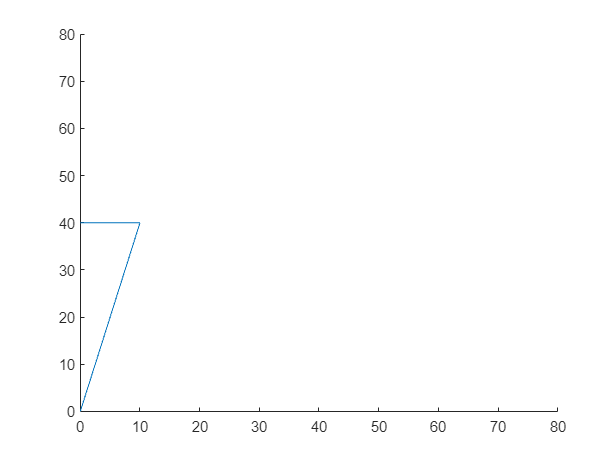

function [A] = DH(a,alpha,d,theta)

A = [cos(theta) -sin(theta)*round(cos(alpha))  sin(theta)*round(sin(alpha)) a*cos(theta);

     sin(theta)  cos(theta)*round(cos(alpha)) -cos(theta)*round(sin(alpha)) a*sin(theta);
     0           round(sin(alpha))             round(cos(alpha))            d ;
     0           0                             0                            1];
end